clear;
clc;
close all;

A=[0 1 0 0; 
    0 -0.818 2.6727 0; 
    0 0 0 1; 
    0 -0.4545 31.1818 0 
    ]

A =          0    1.0000         0         0
         0   -0.8180    2.6727         0
         0         0         0    1.0000
         0   -0.4545   31.1818         0


B=[0; 
    1.8182; 
    0; 
    4.5455
    ]

B =          0
    1.8182
         0
    4.5455


C=[1 0 0 0]

C =      1     0     0     0


D=0

D = 0

% Method 1- poles of tf
[n,d]= ss2tf(A,B,C,D)

n =          0         0    1.8182    0.0000  -44.5460


d =     1.0000    0.8180  -31.1818  -24.2920         0


poles_of_tf= roots(d);
disp('The poles of the transfer function are')

The poles of the transfer function are


poles_of_tf

poles_of_tf =          0
    5.5670
   -5.6067
   -0.7783


% Method 2- eigen values
eigen_values= eig(A);
disp('The eigenvalues of matrix A are')

The eigenvalues of matrix A are


eigen_values

eigen_values =          0
   -5.6067
   -0.7783
    5.5670


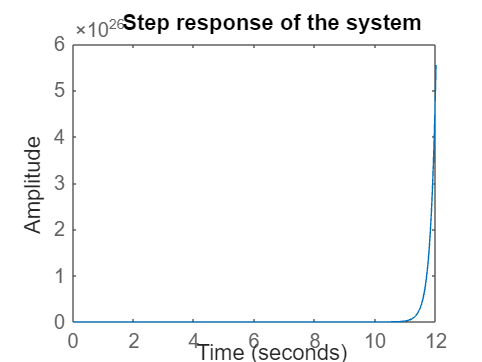

% Method 3- Step response
step(A,B,C,D)
title('Step response of the system')

info=stepinfo(A,B,C,D)

info = 4×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


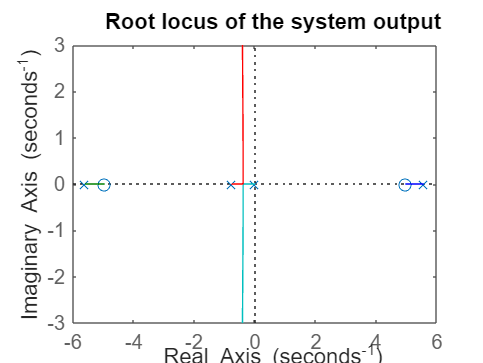

% Method 4- Root locus
rlocus(A,B,C,D)
title('Root locus of the system output')

% Method 5- pzmap 
[P,Z] = pzmap(tf(n,d))

P =          0
    5.5670
   -5.6067
   -0.7783


Z =    -4.9498
    4.9498


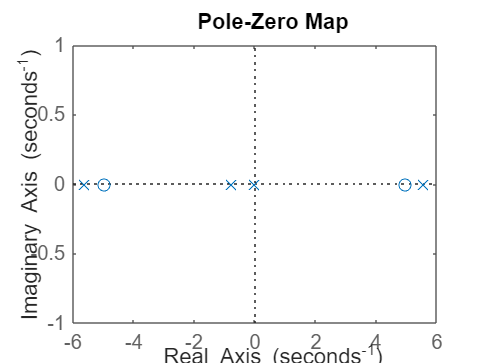

pzplot(tf(n,d))

% Completing Pre requisites for Observer Feedback Controller
P=[B A*B A*A*B A*A*A*B];
Q=[ C; 
    C*A; 
    C*A*A; 
    C*A*A*A
    ];
disp('The rank of matrix P is')

The rank of matrix P is


rank(P)

ans = 4

disp('The rank of matrix Q is')

The rank of matrix Q is


rank(Q)

ans = 4

disp('Order of system is')

Order of system is


size(A,1)

ans = 4

%both are 4 = order of matrix A 
%System is controllable

egnvalues_sfc=[-4 -3 -8 -5];
egnvalues_ofc=[-4 -3 -9 -6];
%for state feedback controller 
K=place(A,B,egnvalues_sfc)

K =   -10.7754   -7.8698   37.9423    7.3679


%for observer feedback controller
L=place(A',C',egnvalues_ofc)'

L = 1.0e+03 *

    0.0212
    0.1849
    0.4650
    2.5916


A_clp = A-B*K

A_clp =          0    1.0000         0         0
   19.5918   13.4909  -66.3140  -13.3964
         0         0         0    1.0000
   48.9795   35.3177 -141.2849  -33.4909


B_clp= B

B_clp =          0
    1.8182
         0
    4.5455


C_clp = C

C_clp =      1     0     0     0


D_clp = D

D_clp = 0

A_clp2 = A-L*C

A_clp2 = 1.0e+03 *

   -0.0212    0.0010         0         0
   -0.1849   -0.0008    0.0027         0
   -0.4650         0         0    0.0010
   -2.5916   -0.0005    0.0312         0


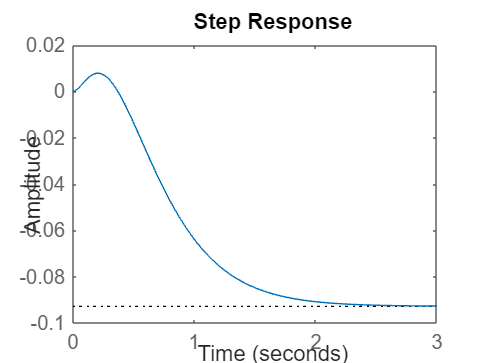

%response of state feeback controller
step(A_clp,B_clp,C_clp,D_clp)

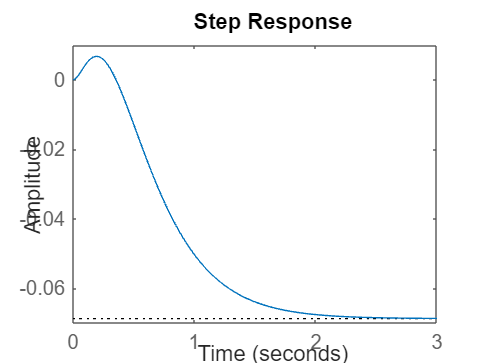


%response of state feeback controller
step(A_clp2,B_clp,C_clp,D_clp)

%Designing PID controller
y=tf(n,d)

y =
 
     1.818 s^2 + 1.615e-15 s - 44.55
  -------------------------------------
  s^4 + 0.818 s^3 - 31.18 s^2 - 24.29 s
 
Continuous-time transfer function.
Model Properties


sys= feedback(y,1)

sys =
 
         1.818 s^2 + 1.615e-15 s - 44.55
  ---------------------------------------------
  s^4 + 0.818 s^3 - 29.36 s^2 - 24.29 s - 44.55
 
Continuous-time transfer function.
Model Properties



p=pidtune(y,'pid')

p =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -0.0552, Ki = -0.000684, Kd = -1.11
 
Continuous-time PID controller in parallel form.
Model Properties


sys_now = feedback(p*y,1)

sys_now =
 
    -2.024 s^4 - 0.1003 s^3 + 49.6 s^2 + 2.458 s + 0.03046
  ----------------------------------------------------------
  s^5 - 1.206 s^4 - 31.28 s^3 + 25.3 s^2 + 2.458 s + 0.03046
 
Continuous-time transfer function.
Model Properties


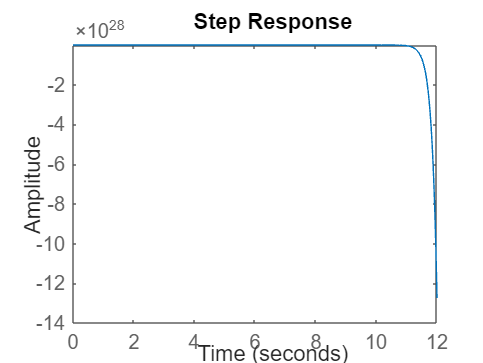

step(sys_now)

dc_gain_before_controller = dcgain(A,B,C,D)

dc_gain_before_controller = Inf

dc_gain_sfc = dcgain(A_clp,B_clp,C_clp,D_clp)

dc_gain_sfc = -0.0928

dc_gain_obs = dcgain(A_clp2,B_clp,C_clp,D_clp)

dc_gain_obs = -0.0687

dc_gain_pid = dcgain(sys_now)

dc_gain_pid = 1

%now computing steady state error
error_before_controller = 1/(1+dc_gain_before_controller)

error_before_controller = 0

error_sfc= 1/(1+dc_gain_sfc)

error_sfc = 1.1023

error_obs= 1/(1+dc_gain_obs)

error_obs = 1.0738

error_pid= 1/(1+dc_gain_pid)

error_pid = 0.5000

% Velocity error constants
kv_before_controller = dcgain(series(tf(1, [1 0]), ss(A, B, C, D))) % Open-loop with ramp input

kv_before_controller = Inf

kv_sfc = dcgain(series(tf(1, [1 0]), ss(A_clp, B_clp, C_clp, D_clp))) % State-feedback control

kv_sfc = Inf

kv_obs = dcgain(series(tf(1, [1 0]), ss(A_clp2, B_clp, C_clp, D_clp))) % Observer-based control

kv_obs = Inf

kv_pid = dcgain(series(tf(1, [1 0]), sys_now))  %PID controller

kv_pid = Inf


% Steady-state errors for ramp input
error_ramp_before_controller = 1 / kv_before_controller

error_ramp_before_controller = 0

error_ramp_sfc = 1 / kv_sfc

error_ramp_sfc = 0

error_ramp_obs = 1 / kv_obs

error_ramp_obs = 0

error_ramp_pid = 1 / kv_pid

error_ramp_pid = 0